# rDCM report - task state

For the past few months we've been excited to learn about Frässle et al.'s work on "regression DCM" (rDCM) that putatively allows one to estimate whole-brain directed connectivity. However, we've had some troubles getting very good results in our simulations.

Before we decide to continue using this tool on empirical data we would like to make sure that the discrepancies in our findings are not due to misuse of the method and apply any possible improvements.

In this notebook we try both to replicate the findings in the papers, and demonstrate the issues we've run into it. We begin by analyzing task-data first as this was the data type on which rDCM was both developed and tested the most. We move onto resting-state in a separate notebook.

## Replication effort

First we replicate some results from Frässle et al. (2018). This is the paper that introduces sparse rDCM and includes several simulations to evaluate the performance of the method. 

We'll try to replicate the simulations in depicted in Frässle et al. (2018) 1B. This network is also used in the TAPAS tutorial so it seems to be regarded as a good case study.

The network consists of ten cyclic communities of five nodes each connected to each other with a single edge. There are 25 inputs with short block stimulations coming on at different time points for the nodes they stimulate. Below they are depicted in five rows for visual clarity. Each input stimulates a single node and all stimulated nodes only have one input.

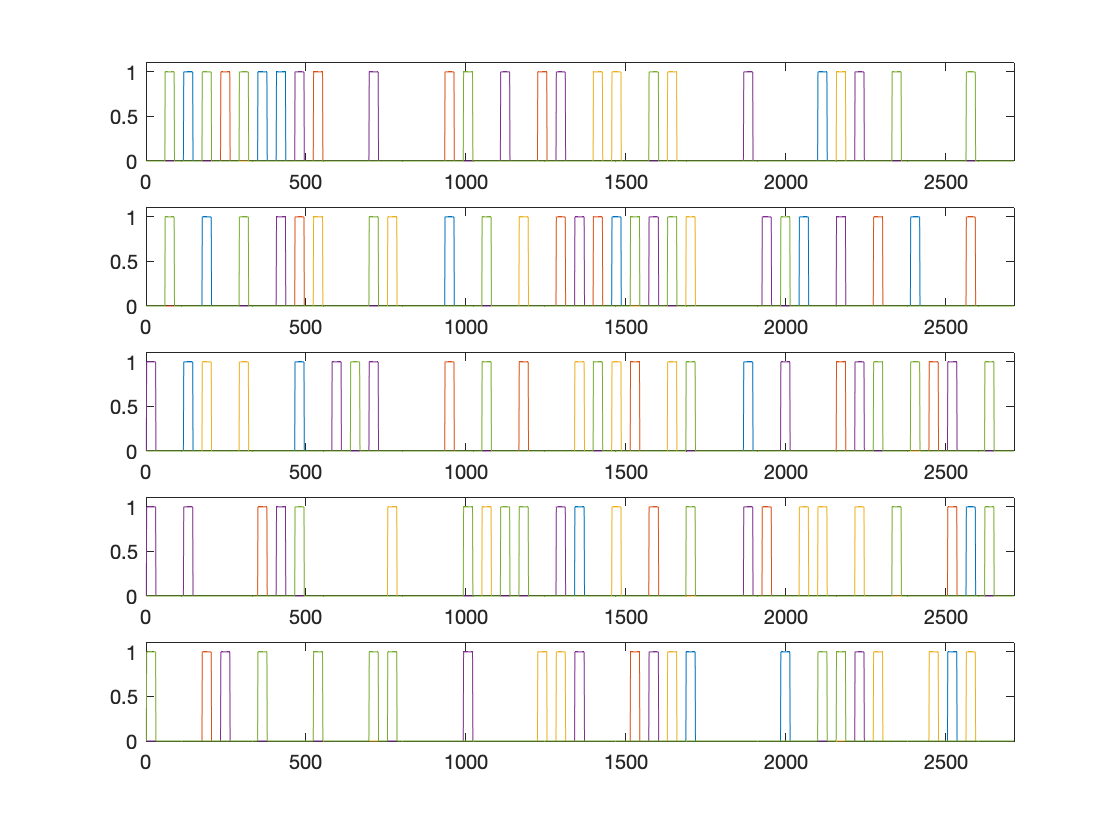

temp = load('tapas-master/rDCM/test/DCM_LargeScaleSmith_model1.mat');
DCM = temp.DCM;
downsampled_task = DCM.U.u(1:16:end,:);

clf
figure
for i=1:5
    subplot(5, 1, i)
    plot(downsampled_task(:, ((i-1)*5+1):(i*5)));
    xlim([0 2714]);
    ylim([0 1.1]);
end

Which nodes does each input stimulate?

Each input stimulates only one node so half of the nodes are not stimulated.

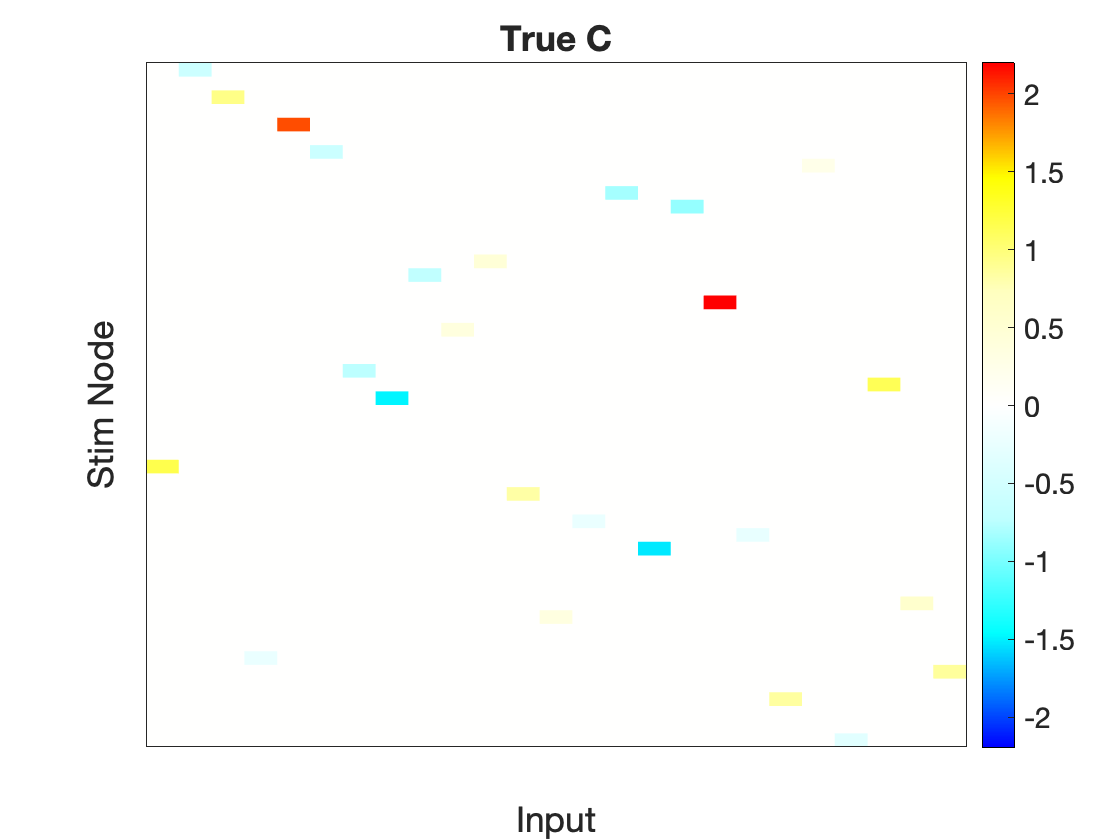

clf
cmap = mycmap();   
h = heatmap(DCM.Tp.C);
h.CellLabelColor = 'none';
h.Colormap = cmap;
col_lims = [abs(min(min(DCM.Tp.C))) abs(max(max(DCM.Tp.C)))];
col_lim = max(col_lims);

h.ColorLimits = [-1*col_lim col_lim];
title("True C"); 
xlabel("Input");
ylabel("Stim Node");
grid(h, 'off');
h.XDisplayLabels = repmat(" ", size(DCM.Tp.C, 2), 1);
h.YDisplayLabels = repmat(" ", size(DCM.Tp.C, 1), 1);
ax = gca;
ax.FontSize = 16;

Based on Eq. 7 in Frässle et al. 2018 pruning happens with the addition of a feature selector Z matrix placed between the design matrix X (that contains the other nodes activity and convolved inputs in the frequency domain) and the parameters vector *θ*. Z is a diagonal matrix with binary indicators that effectively "selects" columns from X. If the diagonal in Z corresponding to a column in X is 0 then no parameter is estimated for that feature (or *θ*=0). Different from the ridge regression optimization is run over not just the connectivity parameters *θ* and measurement noise *τ* but also the feature selector matrix Z.

Z is determined by its diagonal *ζ*'s which come from a binomial distribution with probability *p*. This *p* is what is updated in each variational iteration to update Z.

Estimation begins with a pruning prior $p_0$ that is used in a binomial distribution to determine the initial Z matrix. It then loops through each region and estimates parameters for both connectivity and task involvement for each region depending on the "feature selectivity" vector determined by $p_0$ for that region (detailed below).

In their simulations Frässle et al. found that the recovered parameters especially for connectivity depended on how close the prior $p_0$ was to the true sparseness of the simulation. 

So for computational efficiency we set $p_0$ to be a single value that is the true sparsity of the network. What does inversion with TAPAS look like for the 50 node network with the 25 inputs? 

options.SNR             = 3;
options.y_dt            = 0.5;
options.p0_all          = sum(sum(logical(DCM.Tp.A)))/size(DCM.Tp.A,1)^2;  % single p0 value close to true sparsity (for computational efficiency)
options.iter            = 100;
options.filter_str      = 5;
options.restrictInputs  = 1;

% run a simulation (synthetic) analysis
type = 's';
DCM = tapas_rdcm_generate(DCM, options, options.SNR);
[output, options] = tapas_rdcm_estimate(DCM, type, options, 2);


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 1/1
Processing region: 50/50
Finalize results


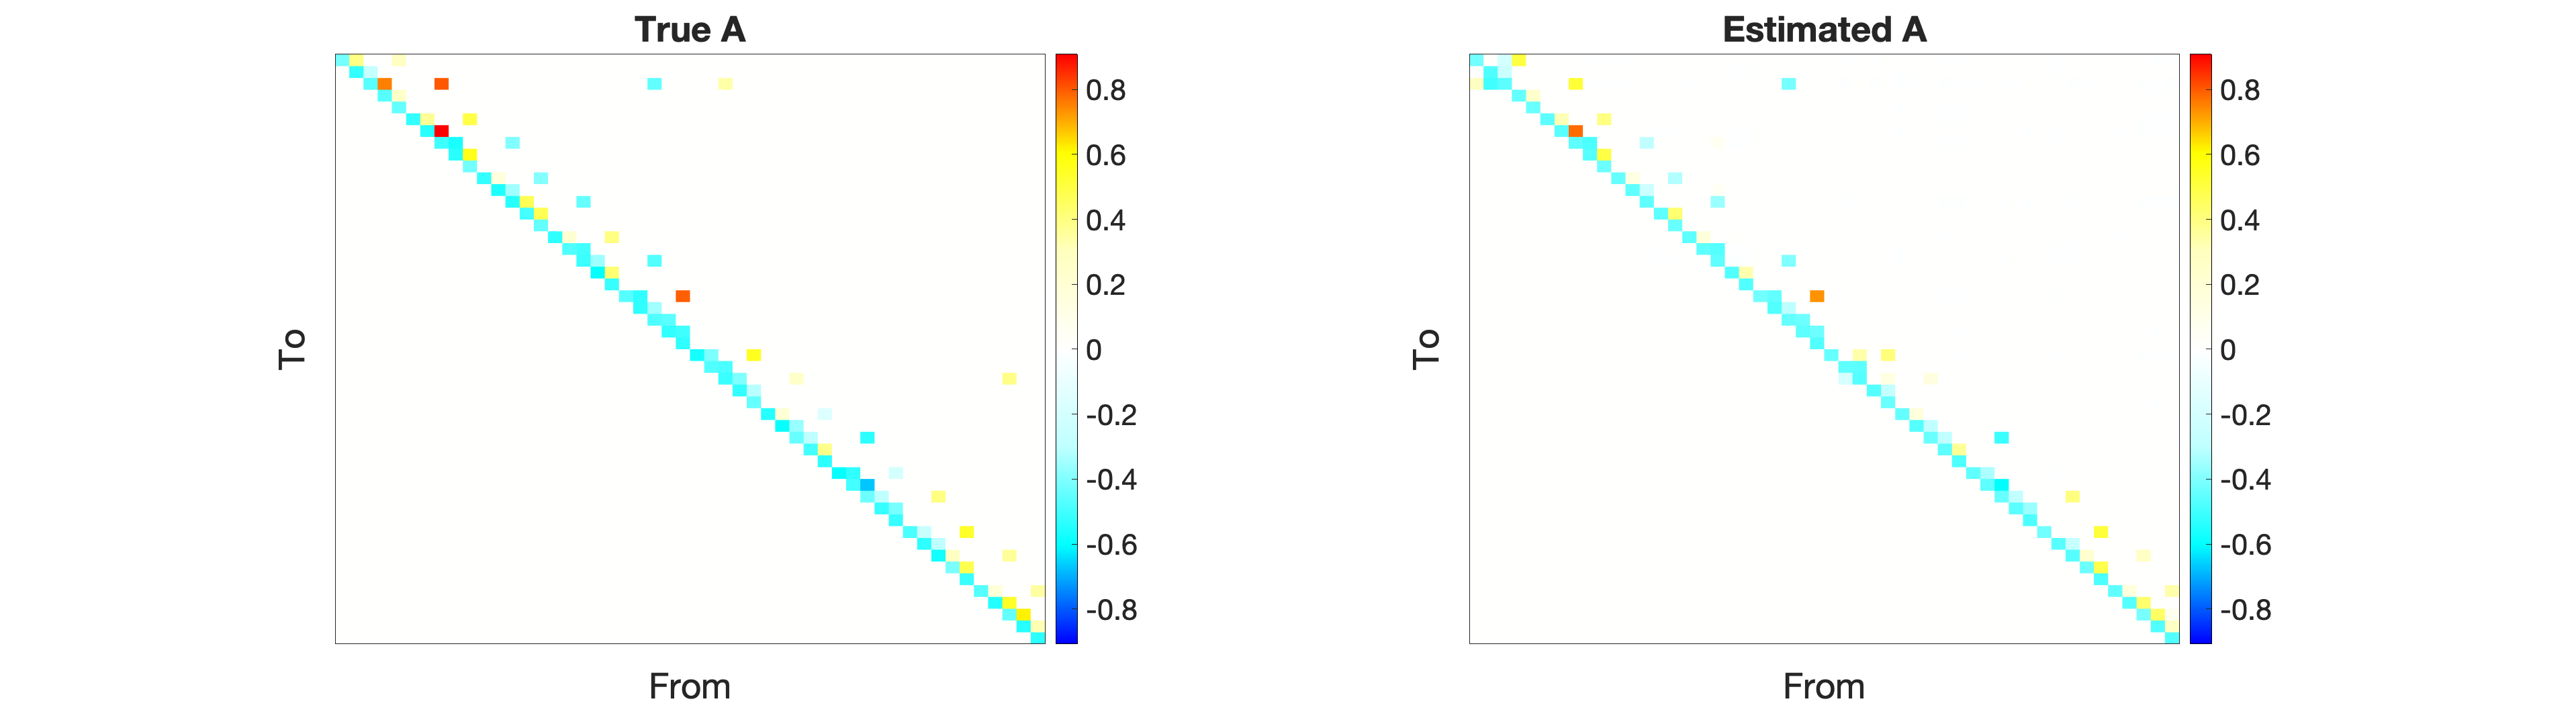

plot_true_est_connectivity(DCM, output, 1);

The estimation appears good but this visualization might be misleading because the diagonals that have strong priors around their true values (close to -0.5) are recovered well but it's not very clear how bad the off-diagonal estimates are.

What does the difference matrix look like? Although the network is very sparse there are some large deviations in the off-diagonal connectivity estimates.

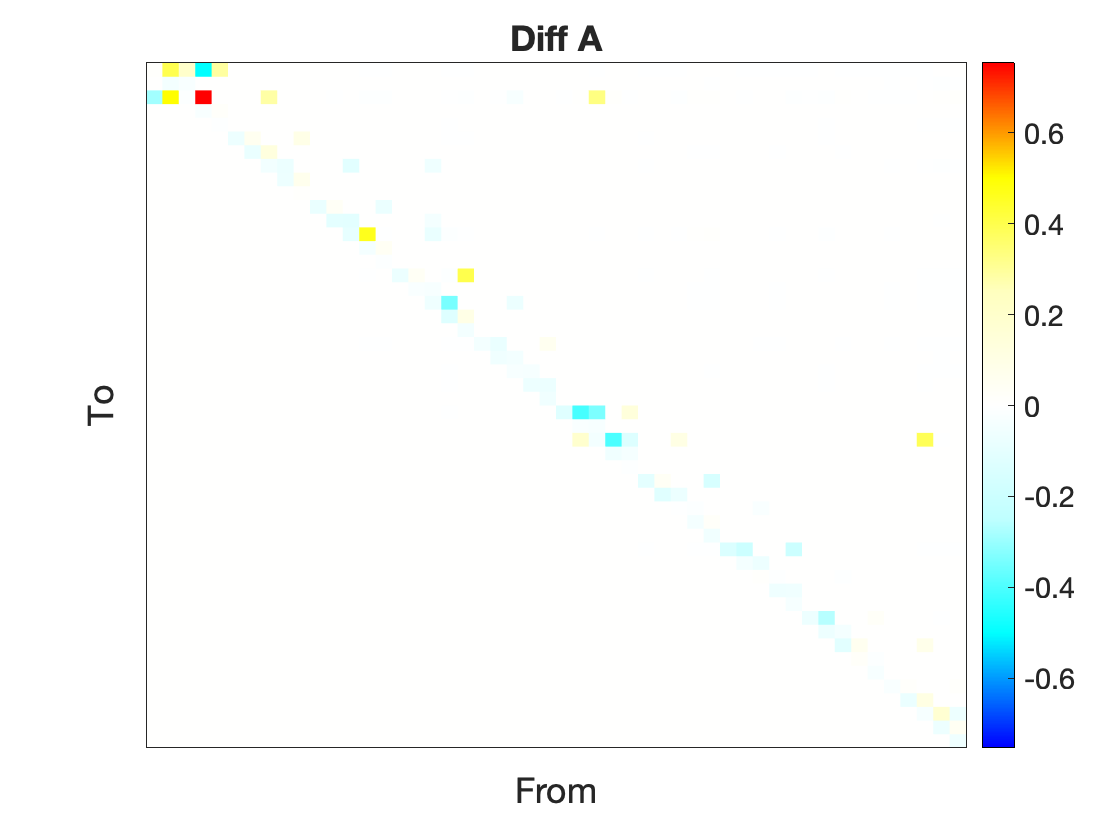

diff_A = DCM.Tp.A - output.Ep.A;
clf
figure
plot_connectivity(diff_A, 1);
title("Diff A"); 
ax = gca;
ax.FontSize = 16;

What is the RMSE for the non-zero off-diagonal connections?

diff_A_upper = triu(diff_A,1);
non_zeros_edges = triu(logical(DCM.Tp.A),1);
sqrt(mean(diff_A_upper(non_zeros_edges).^2))

ans = 0.1965

What is the average absolute difference for the non-zero off-diagonal connections?

mean(abs(diff_A_upper(non_zeros_edges)))

ans = 0.1290

Though both the paper and we so far focused on the recovered parameters a standard model evaluation fit would be to compare the predicted signal to the actual signal.

In the context of rDCM the DV used for estimation is the derivative of each node's activity in the frequency domain. 

What does the predicted versus actual signal look like? Magnitude spectrum plots for the actual and predicted derivatives in the frequency domain for the first 5 nodes.

I'm not very used to looking at spectrum plots so it is a bit difficult to evaluate the importance of the discrepancies for between magnitudes at different frequency bins. Still e.g. for the fifth node the predicted and the actual signals look substantially different.

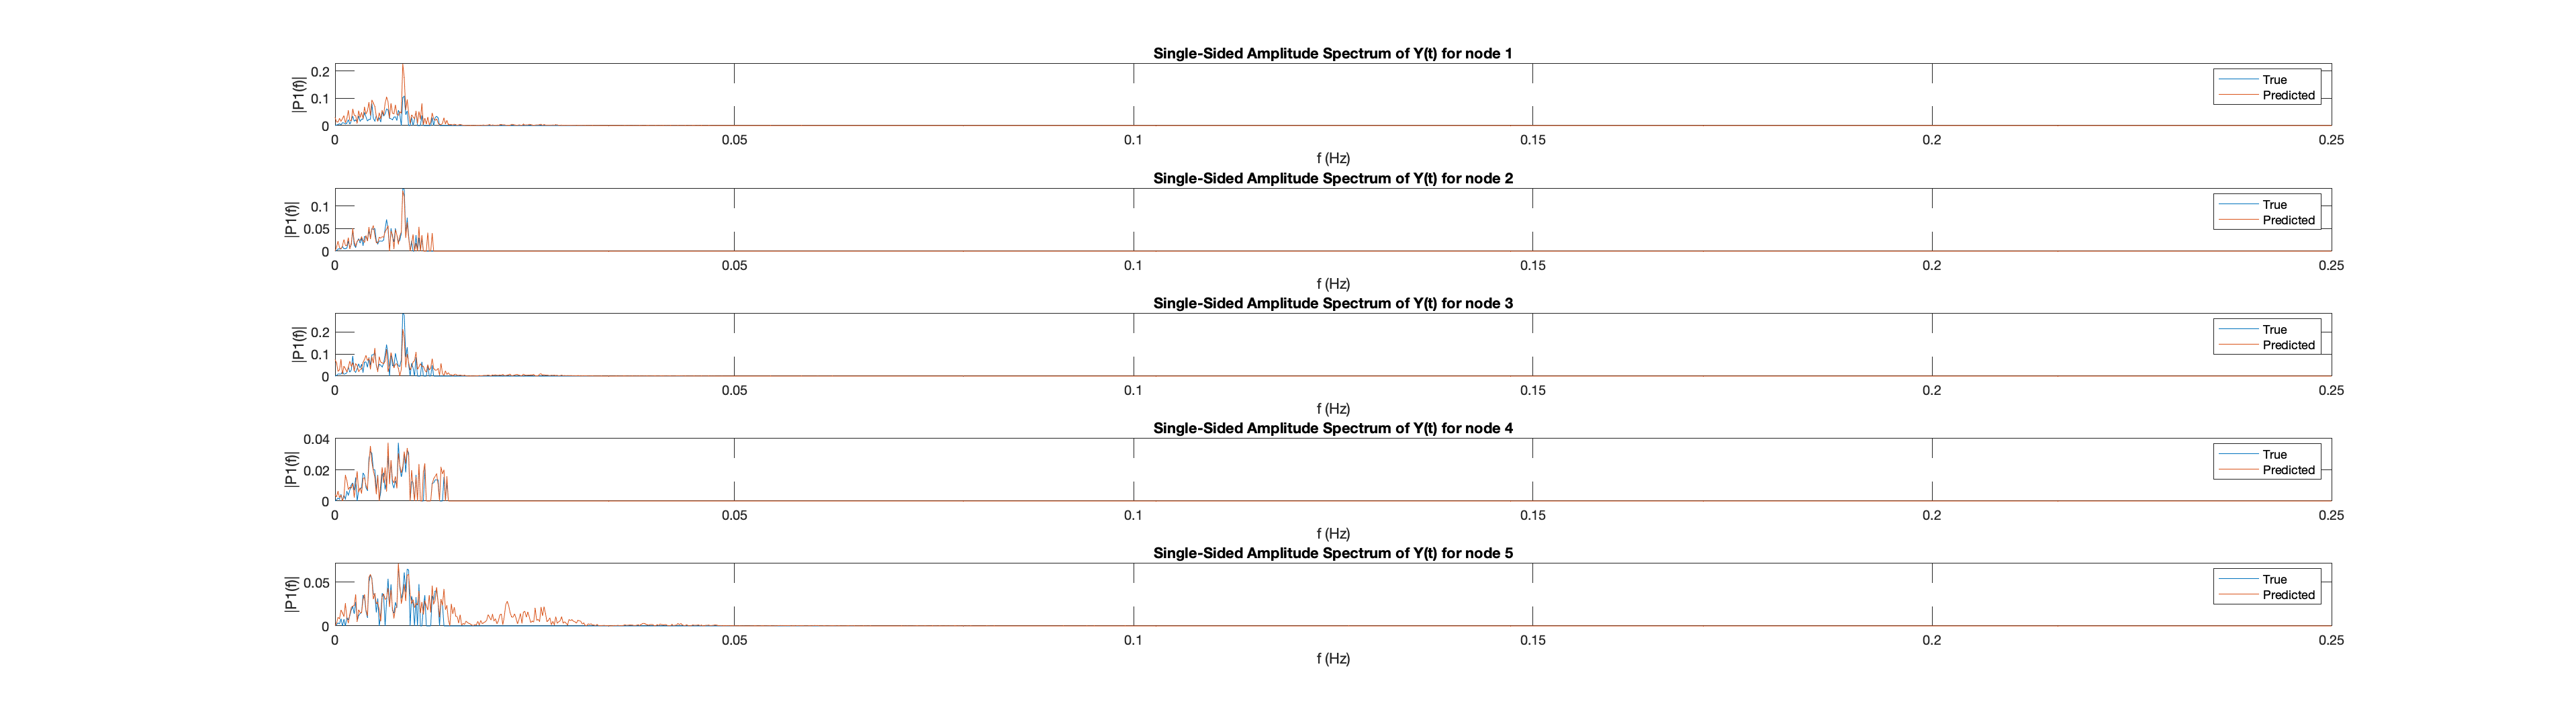

plot_pred_vs_actual(DCM, output, 5, 1)

The model is fit in the frequency domain so it evaluating fit in the time domain might not be an appropriate comparison but just to get a sense of how things look like for the actual and predicted time-series we plot these below for the first five nodes.

Overall the predicted signal captures the broad patterns of the timeseries very well. Due to low pass filtering high frequency oscillations in the true signal seems to be missed.

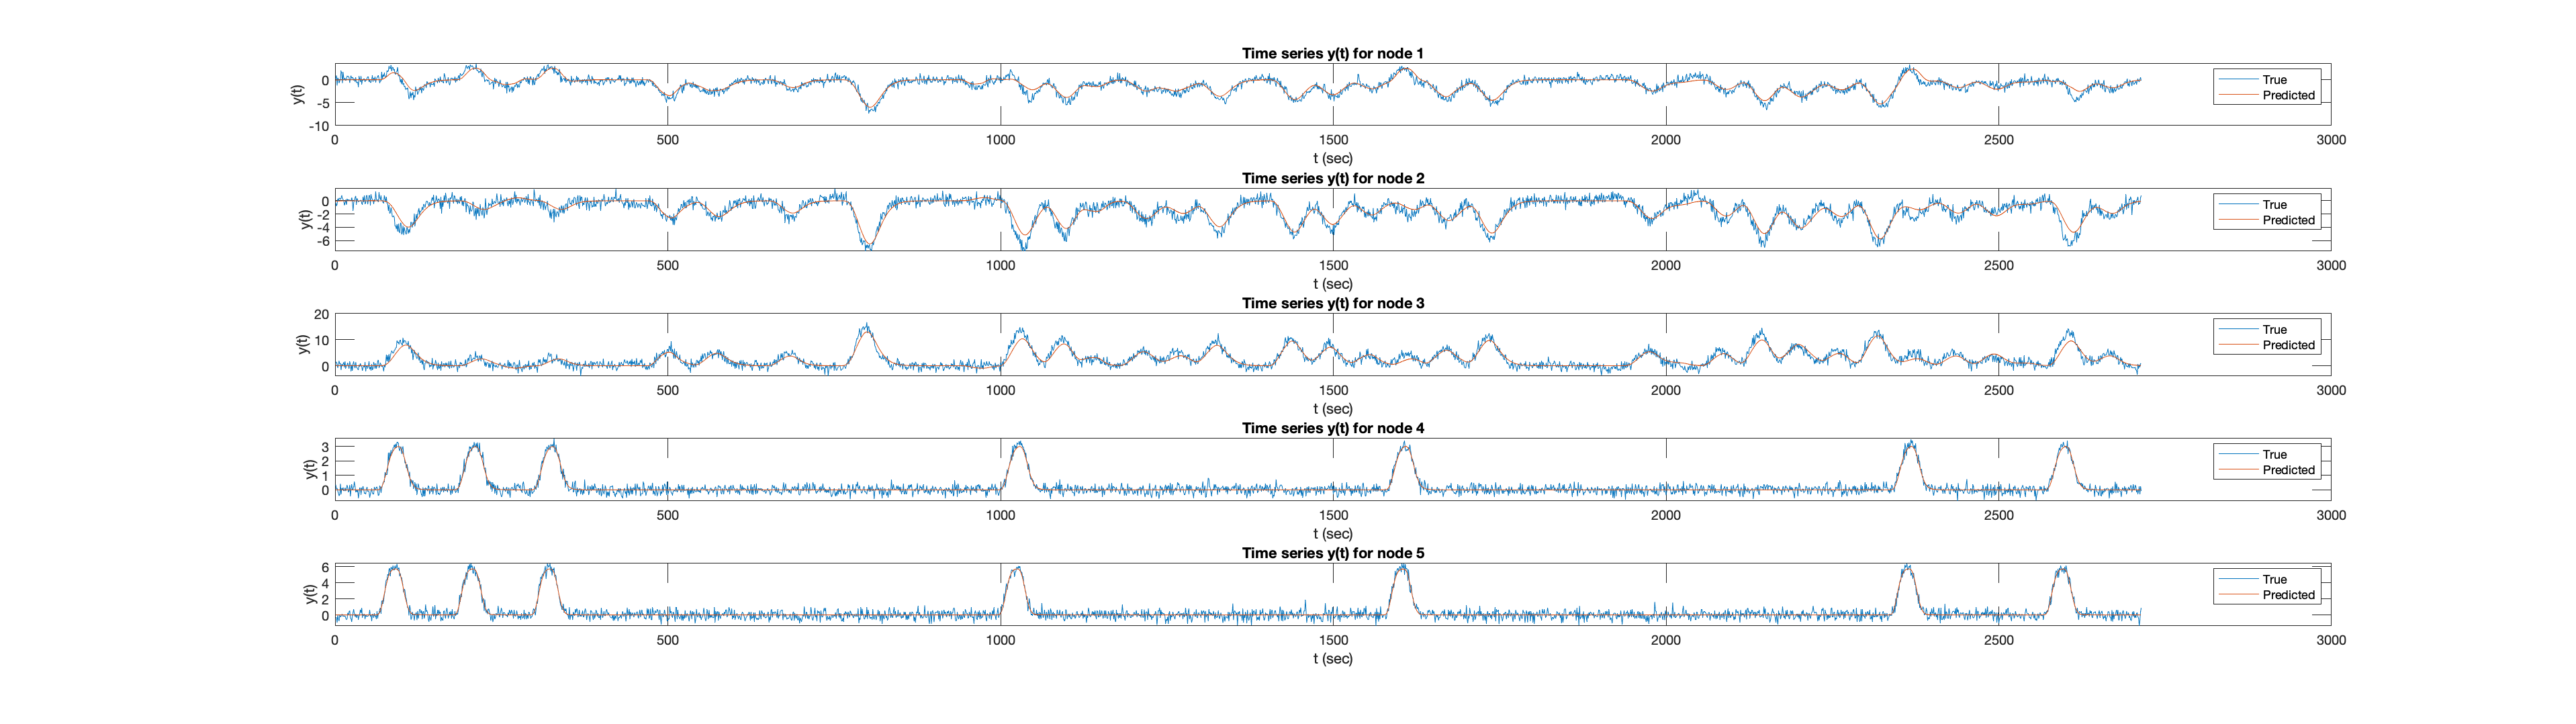

plot_pred_vs_actual(DCM, output, 5, 0)

**Conclusion:** Sparse rDCM can do a good job in pruning a fully connected connectivity matrix to estimate only the true connections with a good pruning prior but even in this potentially best case the connectivity estimates that have wide priors (off-diagonal connections) can diverge largely and the frequency spectra can look very different. It's unclear how much using the estimated connectivity matrix might exacerbate downstream analyses.

## New simulations

In working to understand the details of rDCM we thought it might be helpful to simulate a smaller network and examine how well rDCM recovers known connectivity parameters.

We made a three node network with one "hub" node that connects to both other nodes, one node that is bidirectionally connected to the hub and that is only unidirectionally connected to the hub. 

Importantly this network is much denser compared to example above.

Our simulations suggested that rDCM performed worse in recovering the true connectivity although its success depended on both the network sparsity and both the timing and the scope of task stimulation. Below we detail these effects.

### Task timing effects

#### **Long infrequent stimulation to all nodes**

Using out three node network we first stimulated all nodes with a block design task that had long and infrequent blocks.

stim_options = get_default_stim_options("task");
stim_options.TR = .5; %increase sampling rate

on_len = 64;
off_len = 32;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));
if mod(length(tasktiming), 2)
    tasktiming = [tasktiming 0];
end

stim_options.stim_node = [1,2,3];
stim_options.Tp.C = zeros(stim_options.n,length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.Tp.C(stim_options.stim_node(i),i) = 1;
end
stim_options.c = stim_options.Tp.C; %necessary for correct timeseries prediction using estimated values

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

Plot true connectivity matrix A, true task stimulation matrix C and task timing. Note the last figure appears to have one line only because all nodes' stimulation is overlaid.

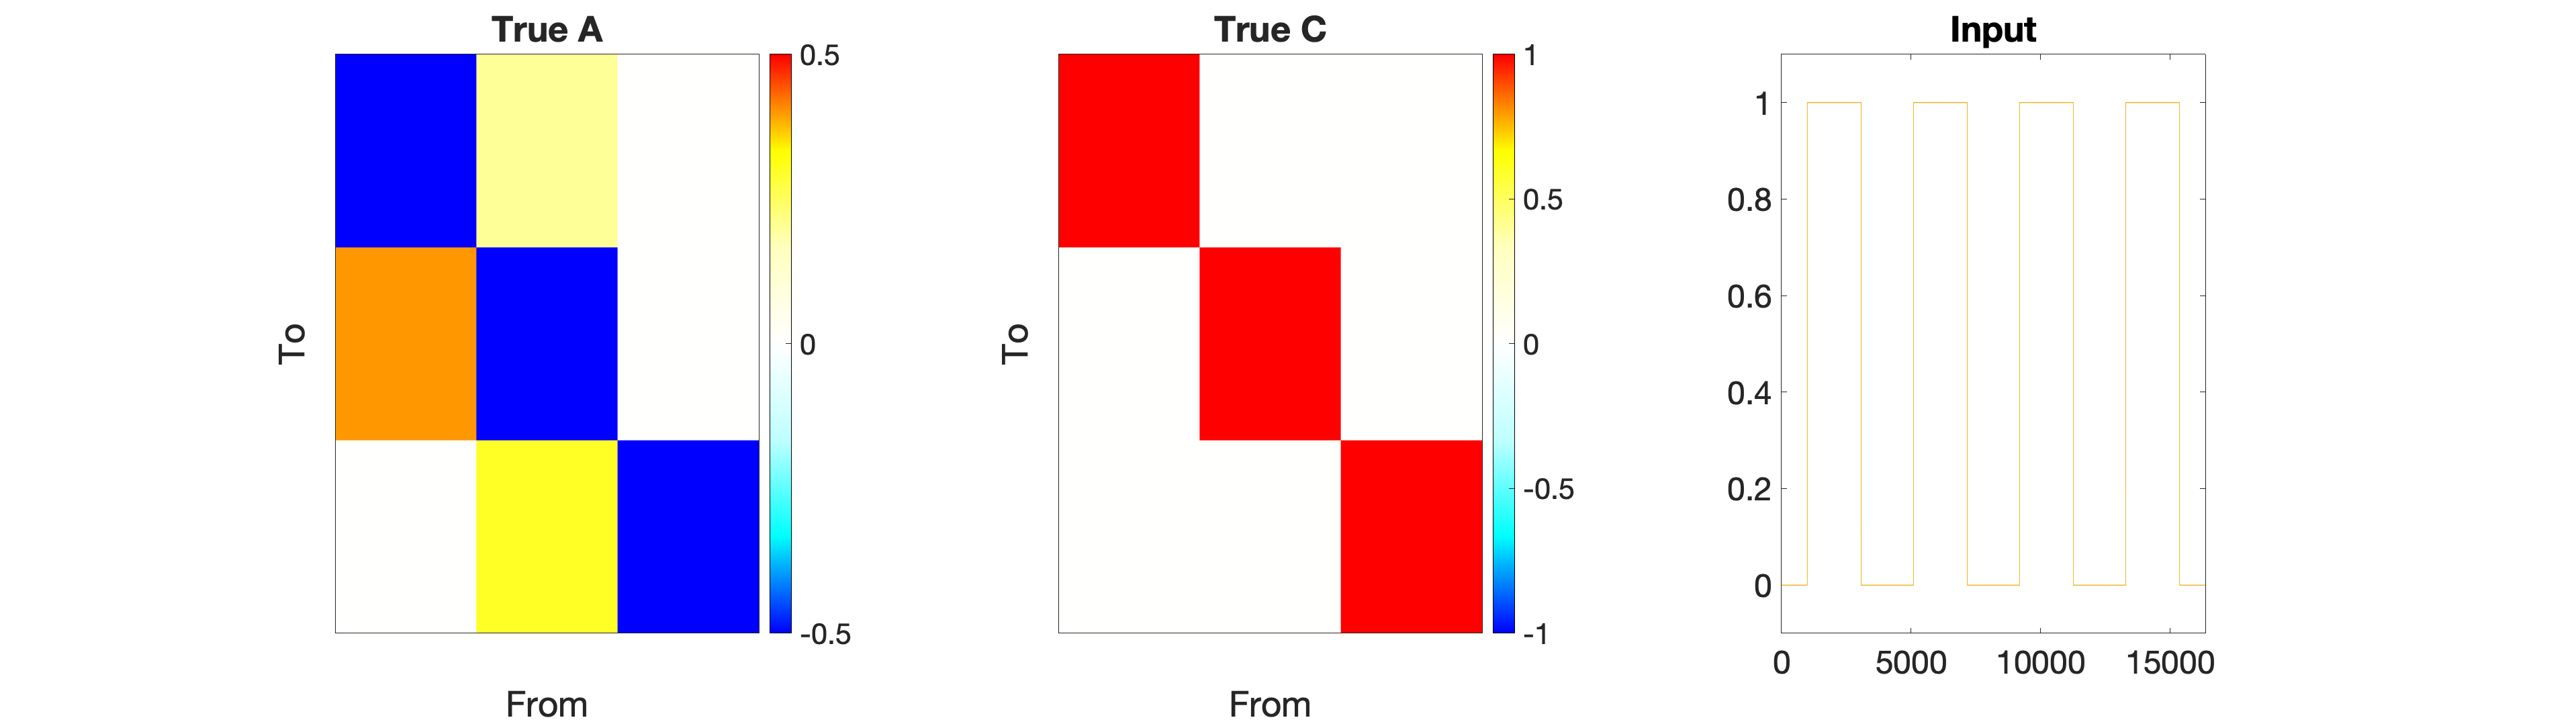

tmp = make_task_fmri(stim_options);
clf
fig = figure();
subplot(1, 3, 1)
plot_connectivity(tmp.Tp.A, 1)

subplot(1, 3, 2)
plot_connectivity(tmp.Tp.C, 1)
title('True C')

subplot(1, 3, 3)
plot(tmp.U.u)
xlim([0 size(tmp.U.u,1)])
ylim([-0.1, 1.1])
title("Input")
ax = gca;
ax.FontSize = 24;

set(fig,'Units','normalized','Position',[0 0 1 .5]); 

Generate 20 subjects and invert. For computational efficiency we again set the pruning prior for sparse rDCM to the true sparsity of the network.

num_subj = 20;
DCM_all  = cell(num_subj, 1);
options_all  = cell(num_subj, 1);
output_all  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all{i}, options_all{i}] = make_task_fmri(stim_options);
    options_all{i}.p0_all = sum(sum(logical(tmp.Tp.A)))/size(tmp.Tp.A,1)^2; %set to true sparsity
    DCM_all{i}.M.noprint = 1;
    [output_all{i}, options_all{i}] = tapas_rdcm_estimate(DCM_all{i}, 's', options_all{i}, 2);
end

Plot output. The average estimated connectivity matrix suggests that the inversion was not successful in pruning (low selectivity).

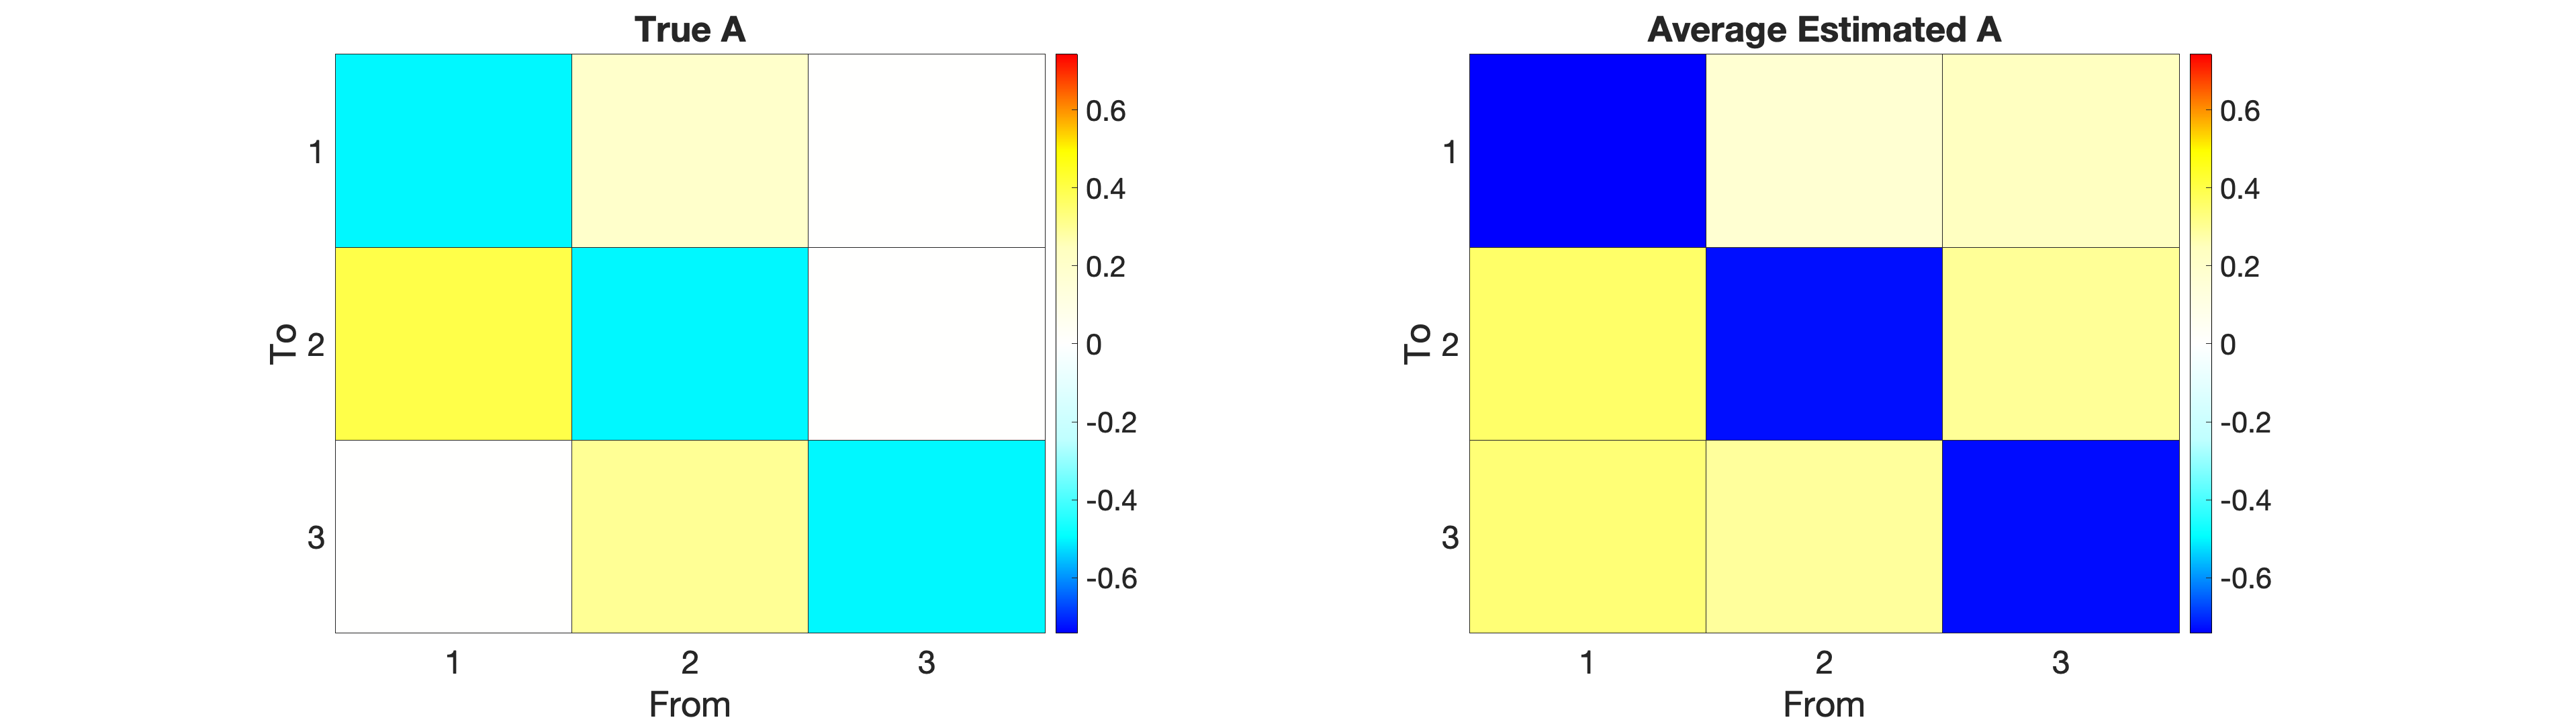

plot_true_est_connectivity(DCM_all{1}, output_all, 1)

Comparing the predicted and actual signal we find that rDCM estimates are consistently lower in all but the smallest frequency bins.

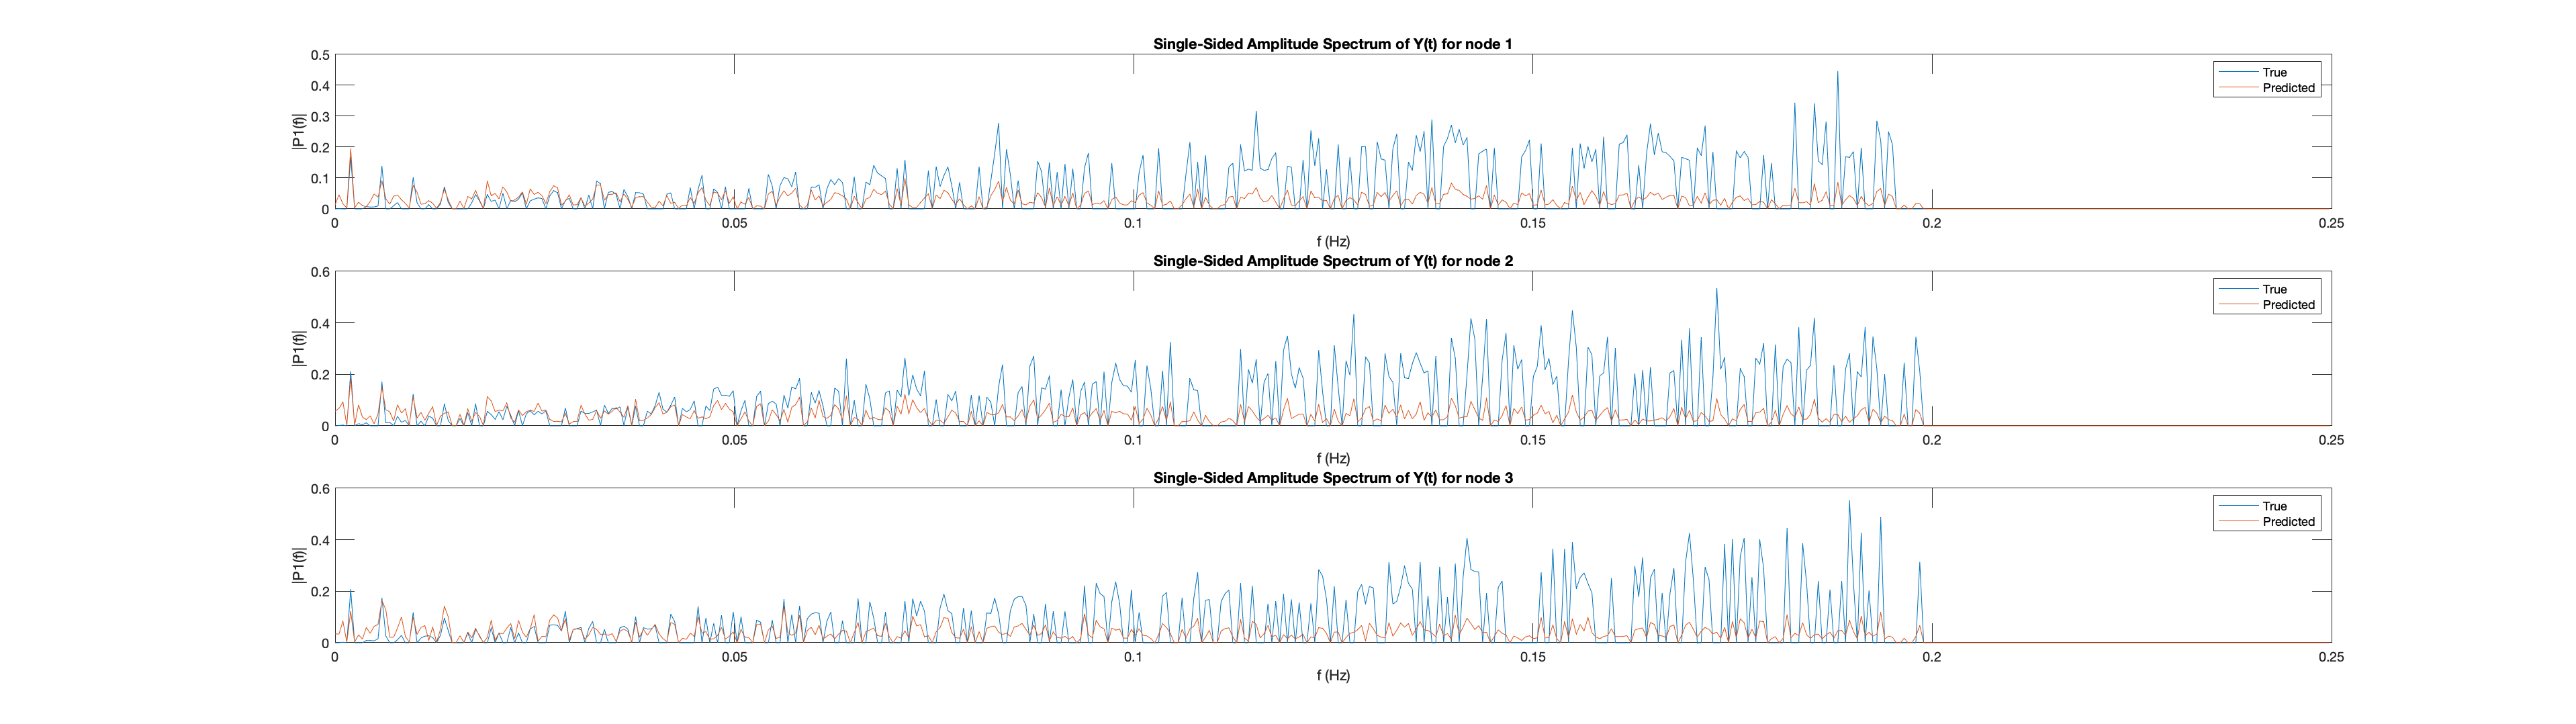

mses = zeros(1, length(output_all));
for i=1:length(output_all)
    mses(i) = cell2mat(cellfun(@(c) {c.statistics.mse}, output_all(i)));
end
[val, ind] = min(mses);
plot_pred_vs_actual(DCM_all{ind}, output_all{ind}, 3, 1)

Despite the discrepancies for high frequencies the predicted signal in the time domain captures the broad patterns of the signals in all nodes surprisingly well.

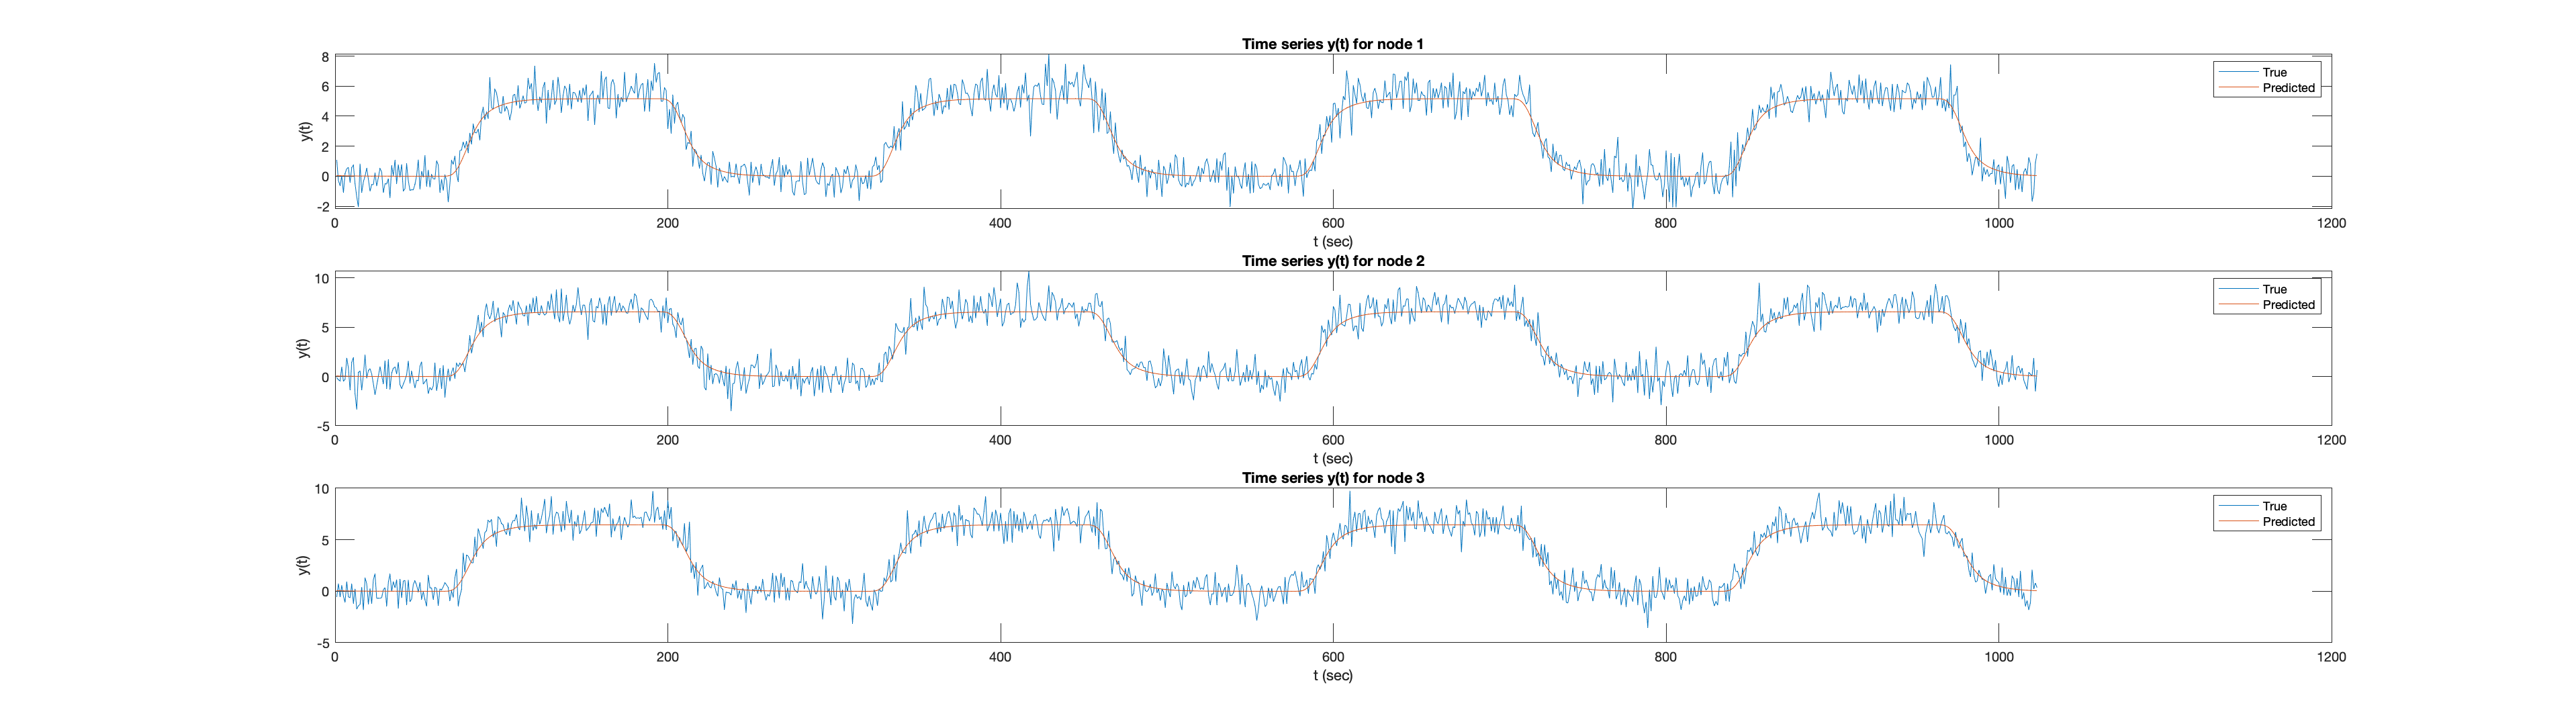

plot_pred_vs_actual(DCM_all{ind}, output_all{ind}, 3, 0)

#### **Short frequent stimulaton to all nodes**

Both the first example in this notebook used in Frässle et al. (2018) and the motor task used in Frässle et al. (2020) have different block task structure than the long infrequent stimulation design we used above. They include short frequent stimulations. So we examined the success of rDCM in our three node network with a stimulation more similar to what it has been tested with.

on_len = 16;
off_len = 8;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));
if mod(length(tasktiming), 2)
    tasktiming = [tasktiming 0];
end

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

Plot true connectivity matrix A, true task stimulation matrix C and task timing. Note the last figure appears to have one line only because all nodes' stimulation is overlaid.

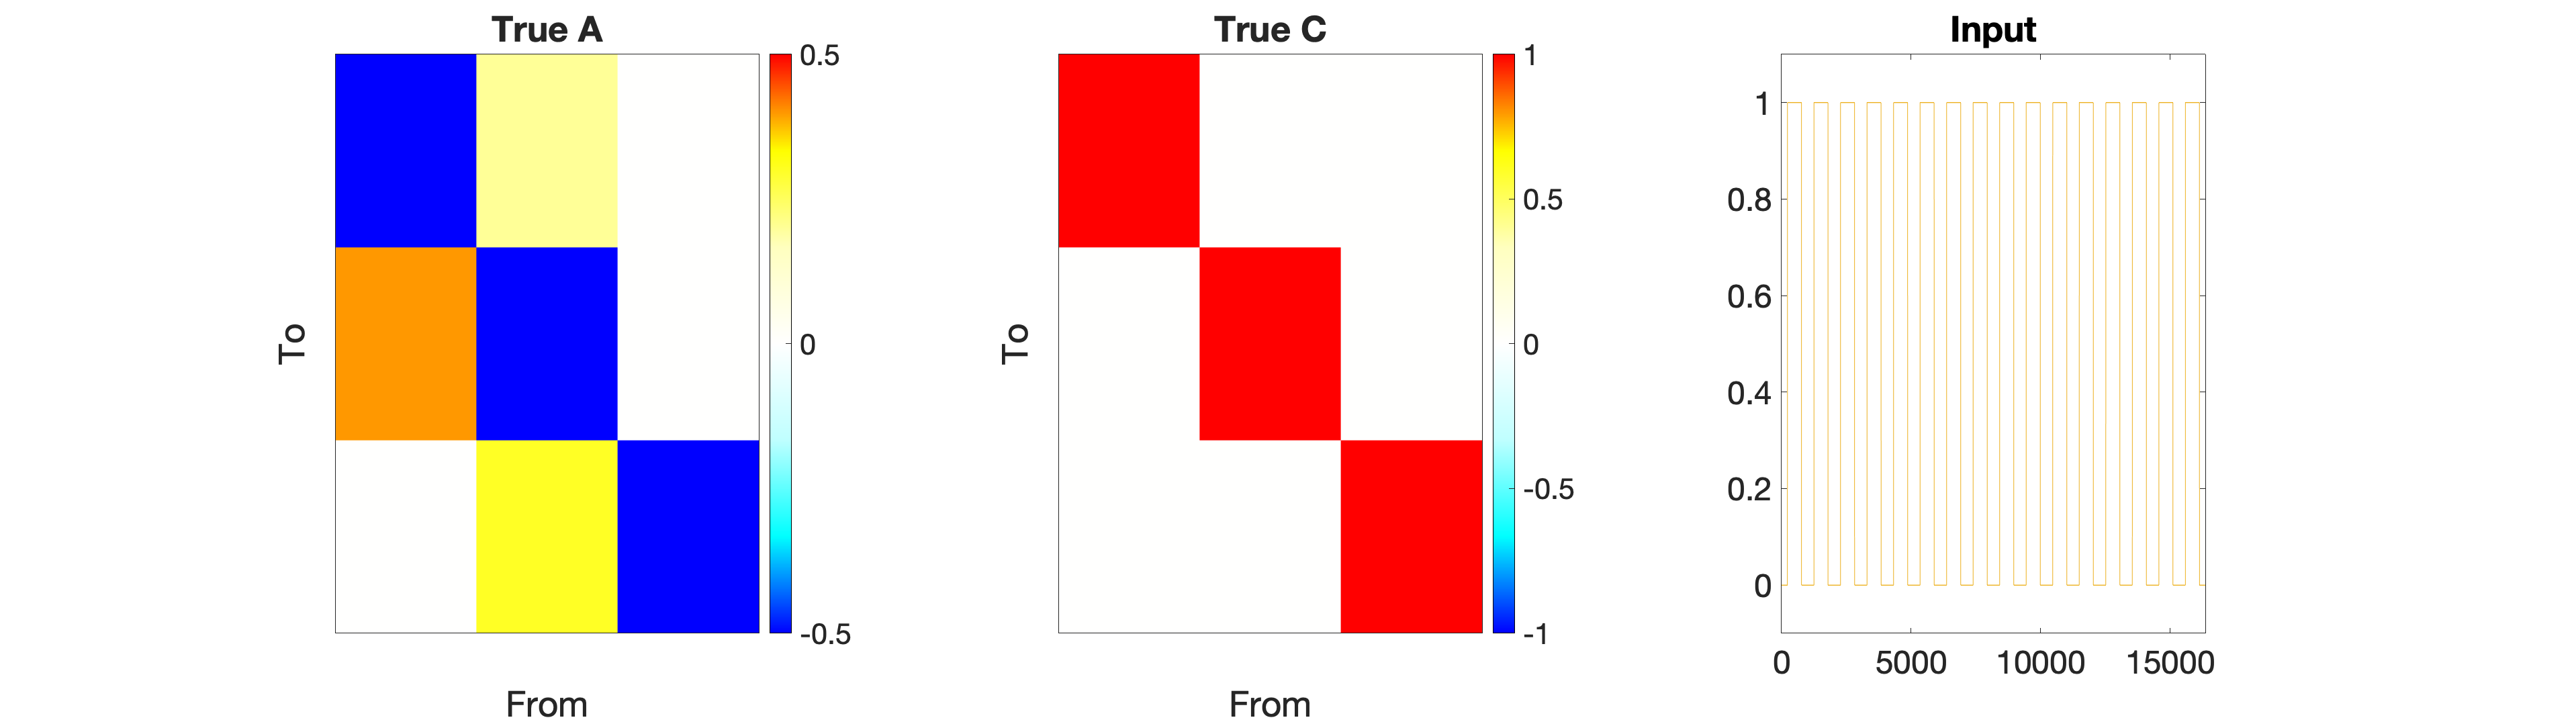

tmp = make_task_fmri(stim_options);
clf
fig = figure();
subplot(1, 3, 1)
plot_connectivity(tmp.Tp.A, 1)

subplot(1, 3, 2)
plot_connectivity(tmp.Tp.C, 1)
title('True C')

subplot(1, 3, 3)
plot(tmp.U.u)
xlim([0 size(tmp.U.u,1)])
ylim([-0.1, 1.1])
title("Input")
ax = gca;
ax.FontSize = 24;

set(fig,'Units','normalized','Position',[0 0 1 .5]); 

Generate 20 subjects and invert

num_subj = 20;
DCM_all  = cell(num_subj, 1);
options_all  = cell(num_subj, 1);
output_all  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all{i}, options_all{i}] = make_task_fmri(stim_options);
    options_all{i}.p0_all = sum(sum(logical(tmp.Tp.A)))/size(tmp.Tp.A,1)^2; %set to true sparsity
    DCM_all{i}.M.noprint = 1;
    [output_all{i}, options_all{i}] = tapas_rdcm_estimate(DCM_all{i}, 's', options_all{i}, 2);
end

Plot output

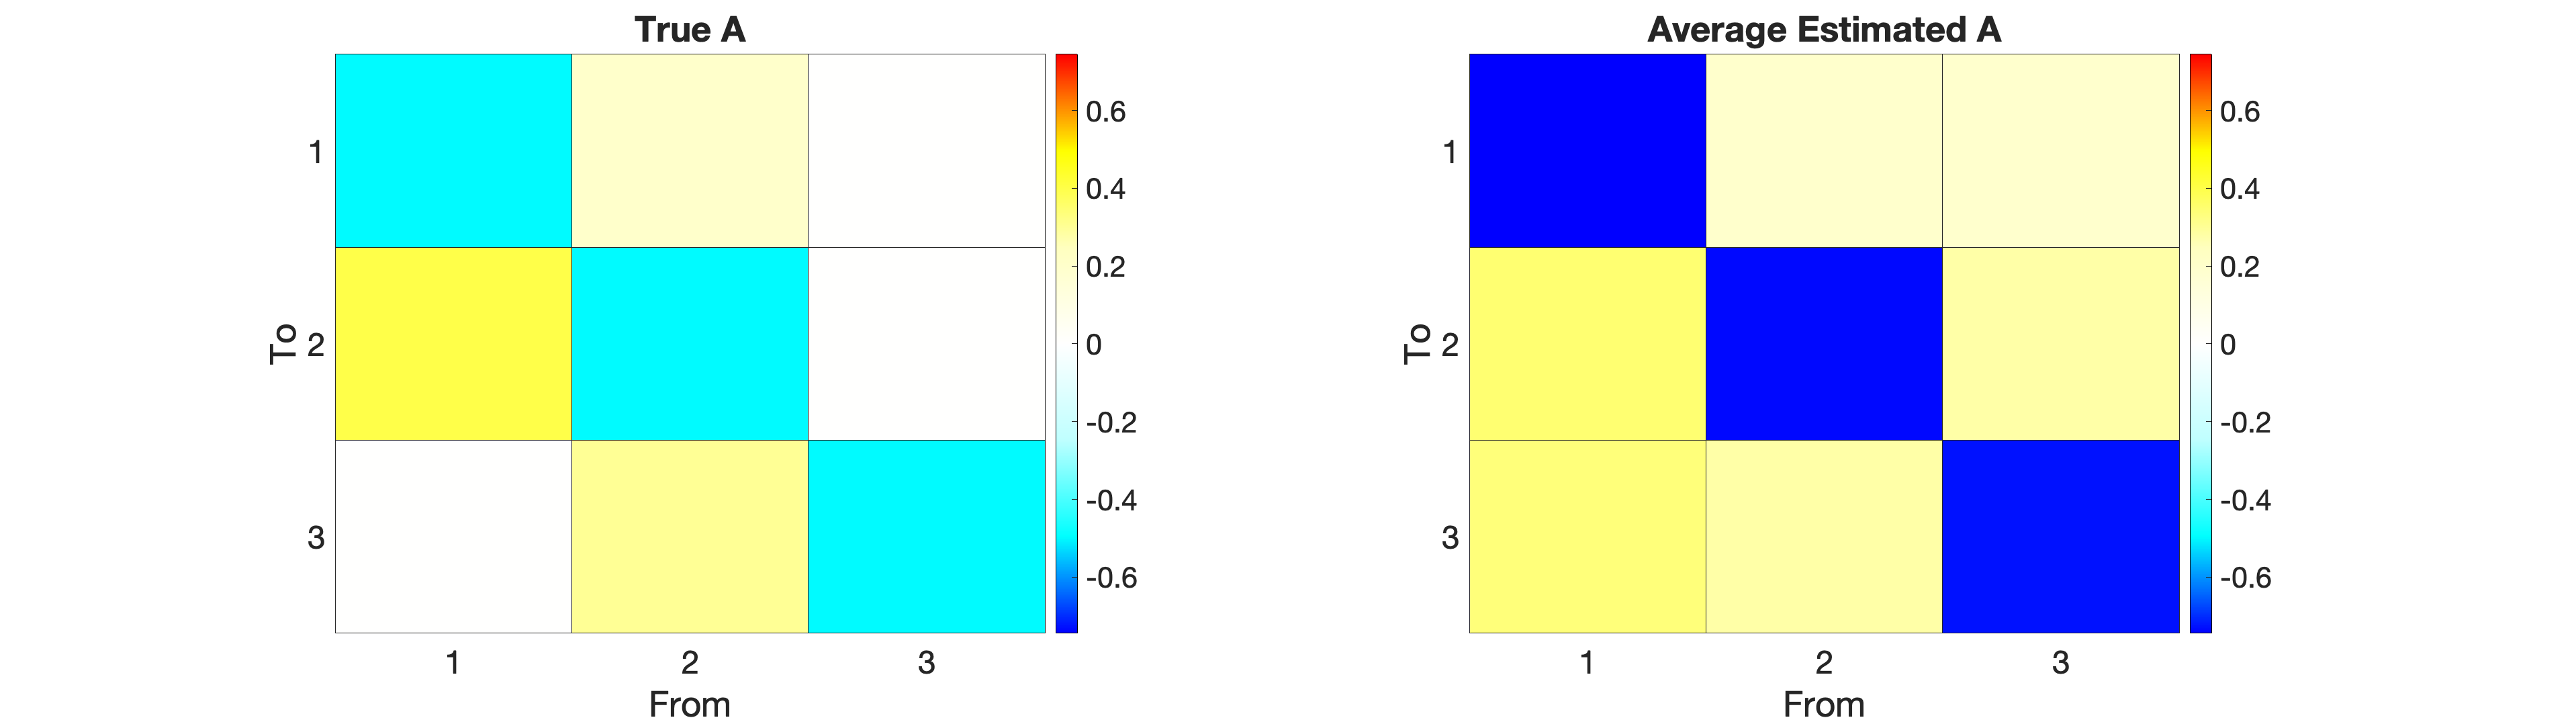

plot_true_est_connectivity(DCM_all{1}, output_all, 1)

Compare predicted and actual signal

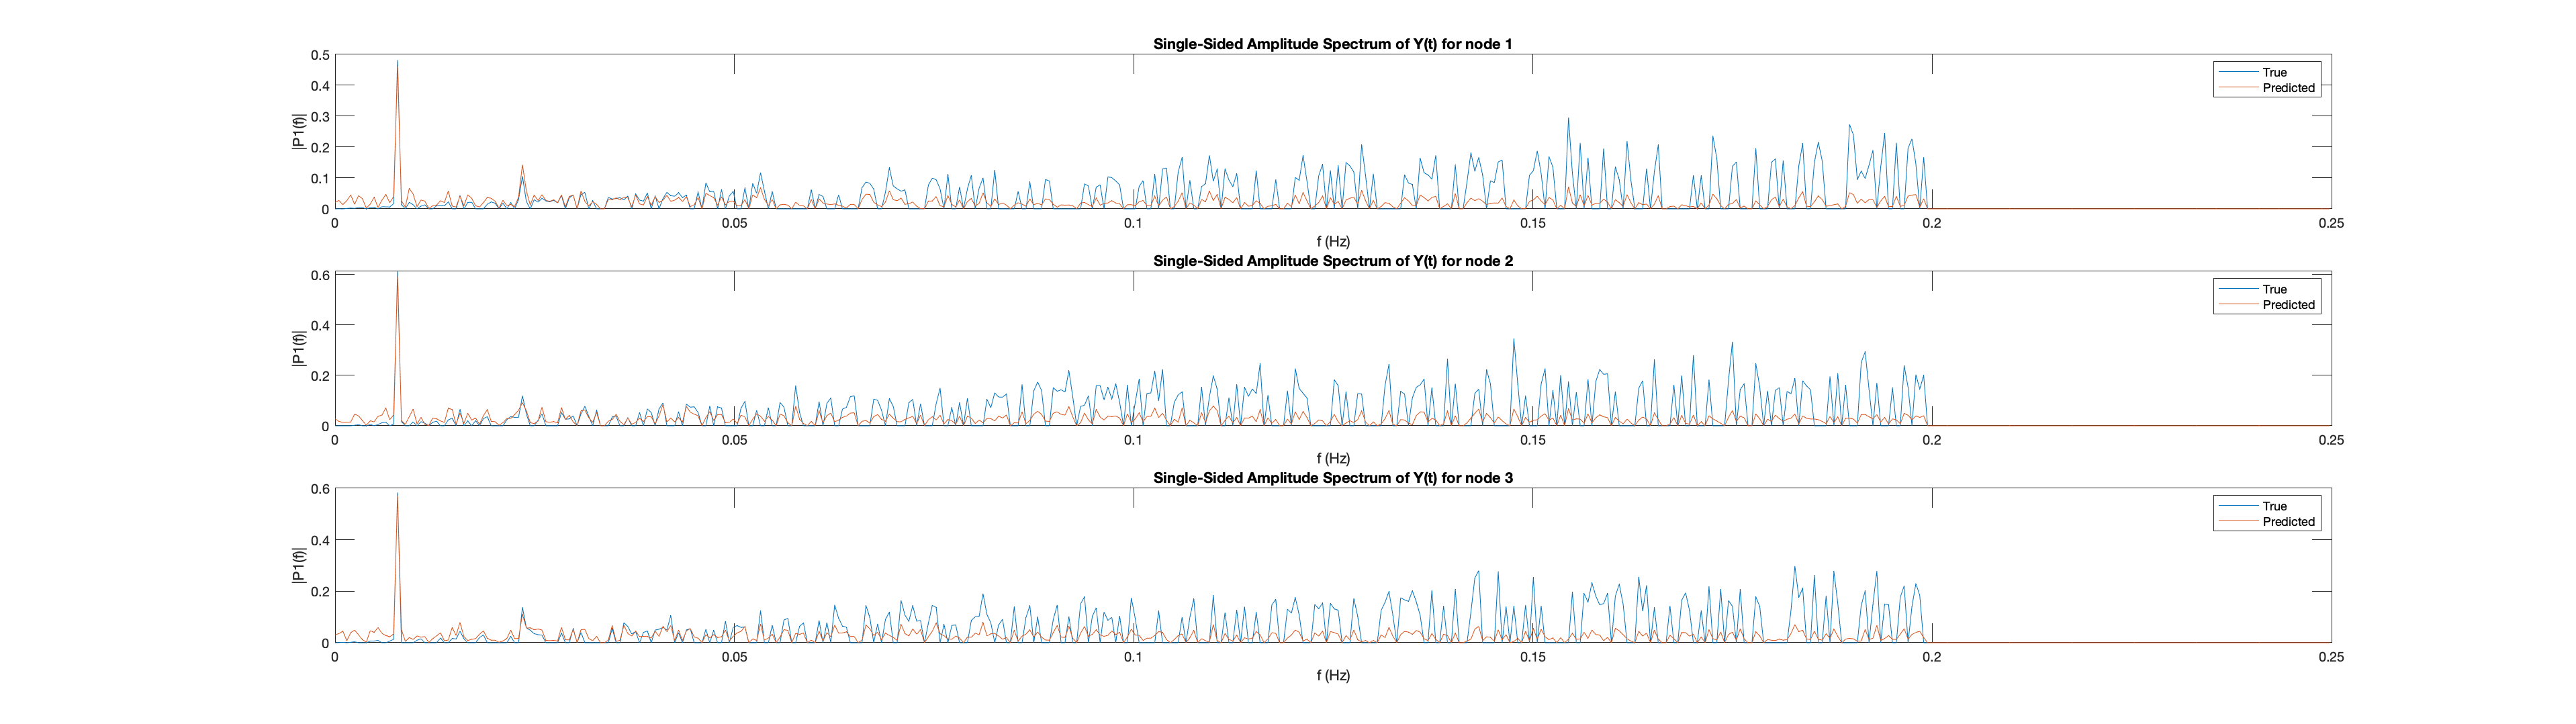

mses = zeros(1, length(output_all));
for i=1:length(output_all)
    mses(i) = cell2mat(cellfun(@(c) {c.statistics.mse}, output_all(i)));
end
[val, ind] = min(mses);
plot_pred_vs_actual(DCM_all{ind}, output_all{ind}, 3, 1)

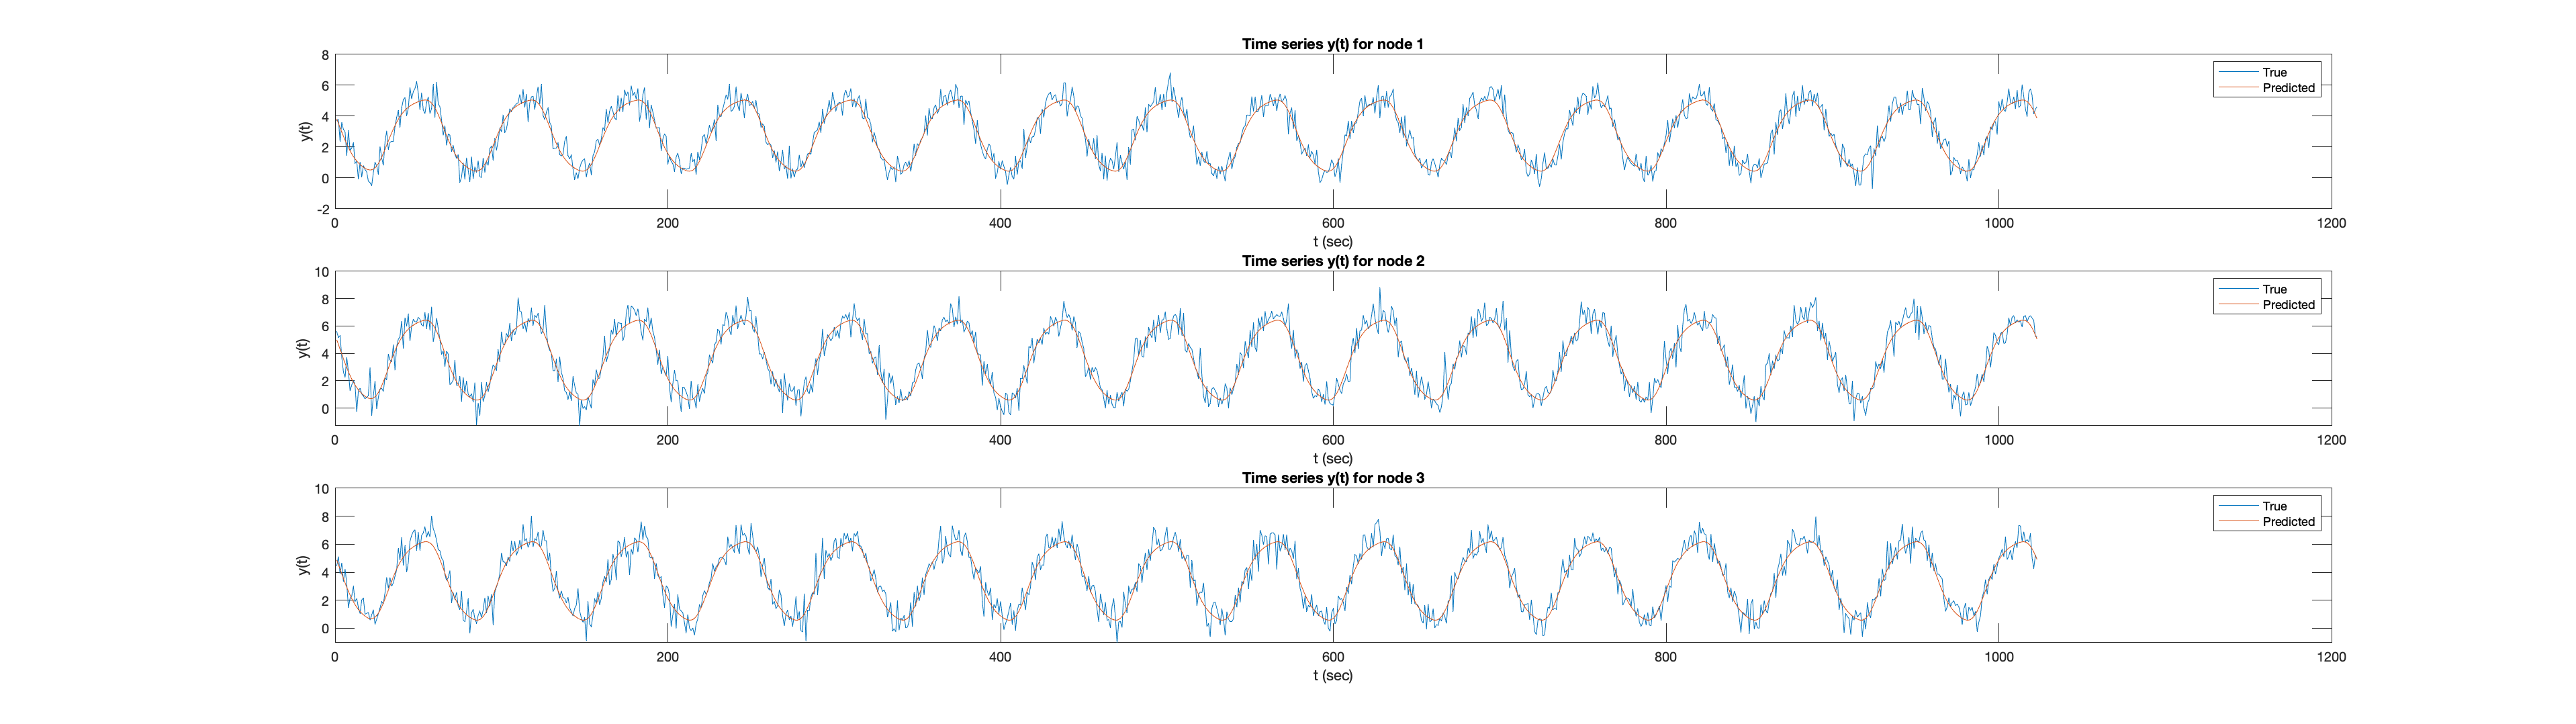

plot_pred_vs_actual(DCM_all{ind}, output_all{ind}, 3, 0)

#### **Long stimulation to one node**

on_len = 64;
off_len = 32;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));
if mod(length(tasktiming), 2)
    tasktiming = [tasktiming 0];
end

stim_options.stim_node = 2;
stim_options.Tp.C = zeros(stim_options.n,length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.Tp.C(stim_options.stim_node(i),i) = 1;
end
stim_options.c = stim_options.Tp.C;

stim_options.u = zeros(length(tasktiming), length(stim_options.stim_node));
for i=1:length(stim_options.stim_node)
    stim_options.u(:, i) = tasktiming;
end

Plot true network, true C and task

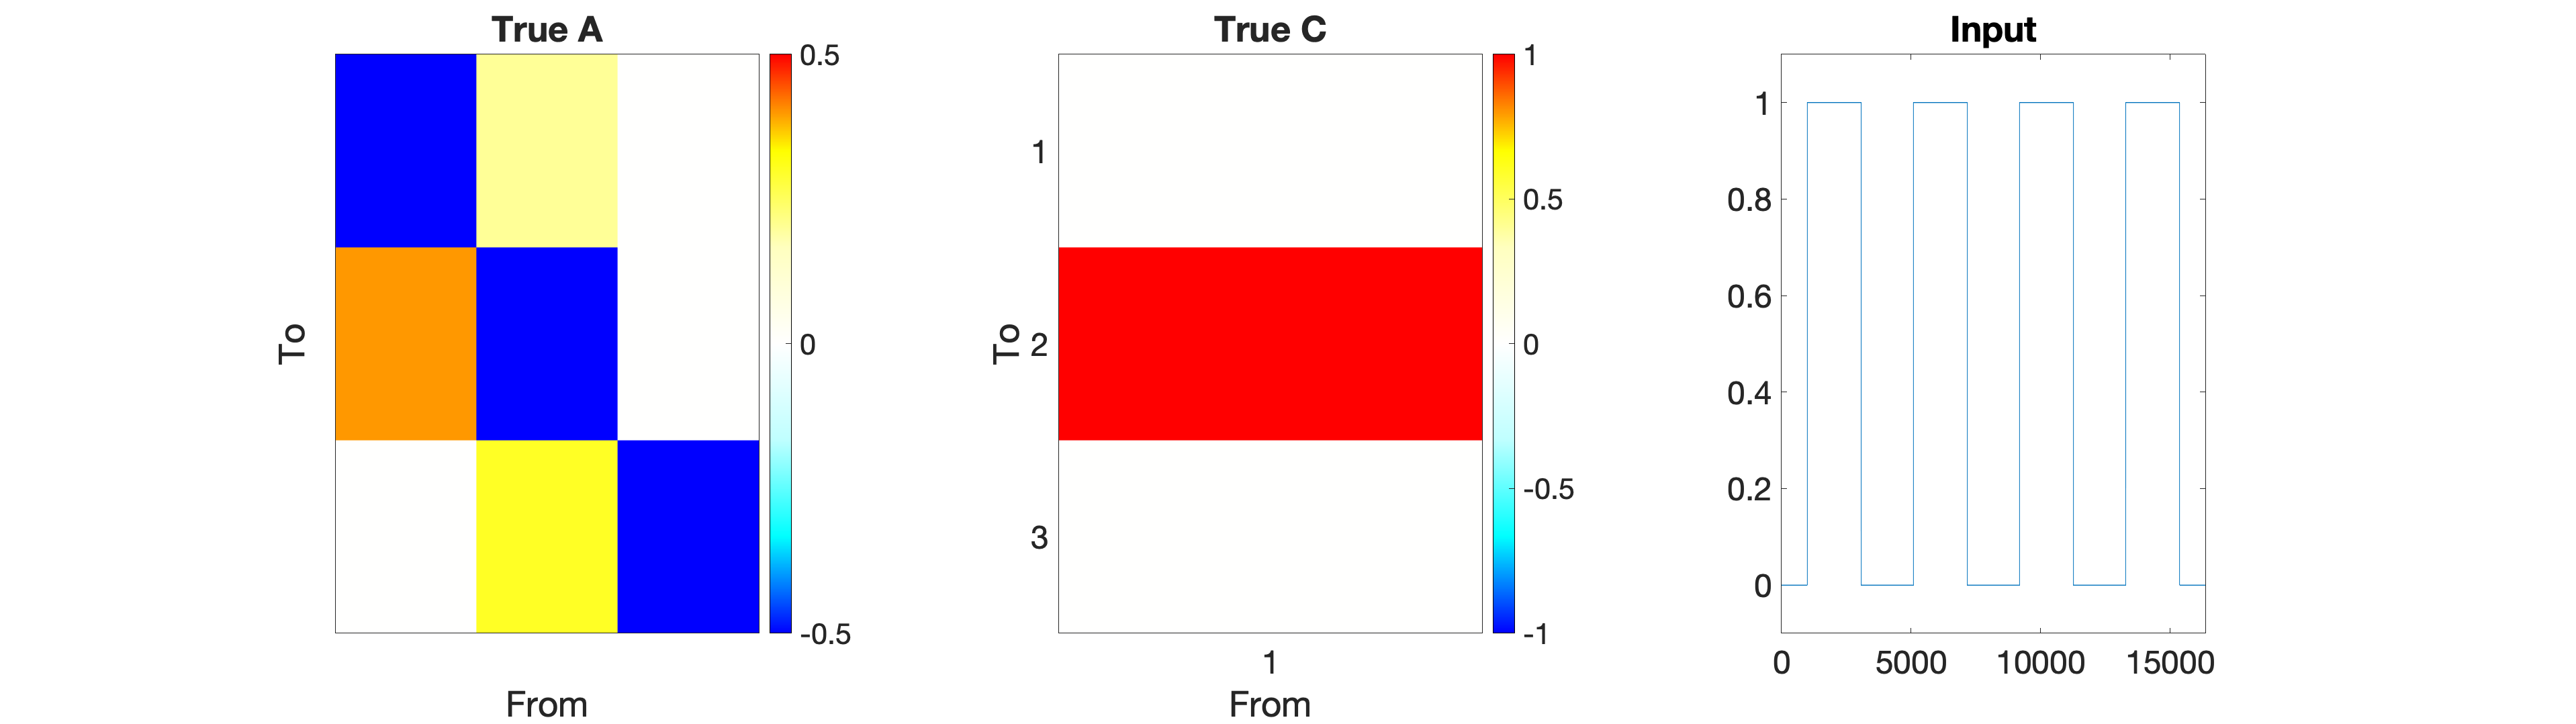

tmp = make_task_fmri(stim_options);
clf
fig = figure();
subplot(1, 3, 1)
plot_connectivity(tmp.Tp.A, 1)

subplot(1, 3, 2)
plot_connectivity(tmp.Tp.C, 0)
title('True C')

subplot(1, 3, 3)
plot(tmp.U.u)
xlim([0 size(tmp.U.u,1)])
ylim([-0.1, 1.1])
title("Input")
ax = gca;
ax.FontSize = 24;

set(fig,'Units','normalized','Position',[0 0 1 .5]); 

Generate 20 subjects and invert

num_subj = 20;
DCM_all  = cell(num_subj, 1);
options_all  = cell(num_subj, 1);
output_all  = cell(num_subj, 1);

for i=1:num_subj
    [DCM_all{i}, options_all{i}] = make_task_fmri(stim_options);
    options_all{i}.p0_all = sum(sum(logical(tmp.Tp.A)))/size(tmp.Tp.A,1)^2; %set to true sparsity
    DCM_all{i}.M.noprint = 1;
    [output_all{i}, options_all{i}] = tapas_rdcm_estimate(DCM_all{i}, 's', options_all{i}, 2);
end

Plot output

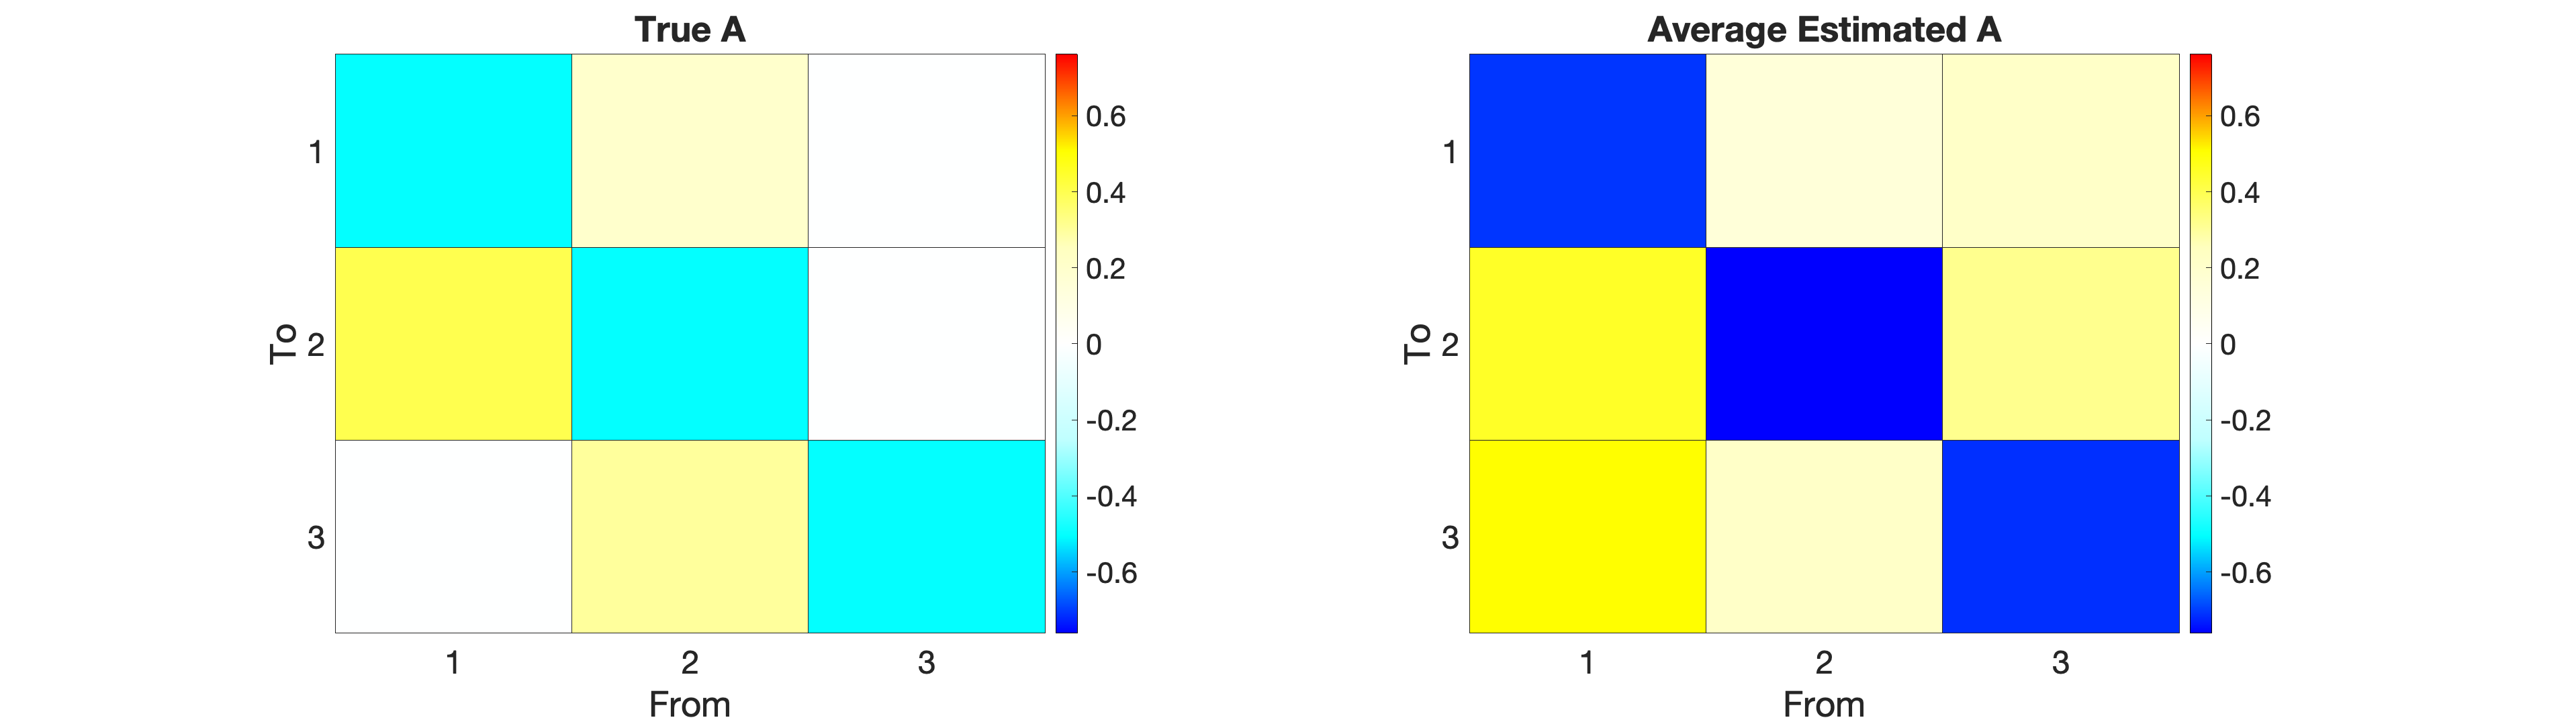

plot_true_est_connectivity(DCM_all{1}, output_all, 1)

Compare predicted and actual signal

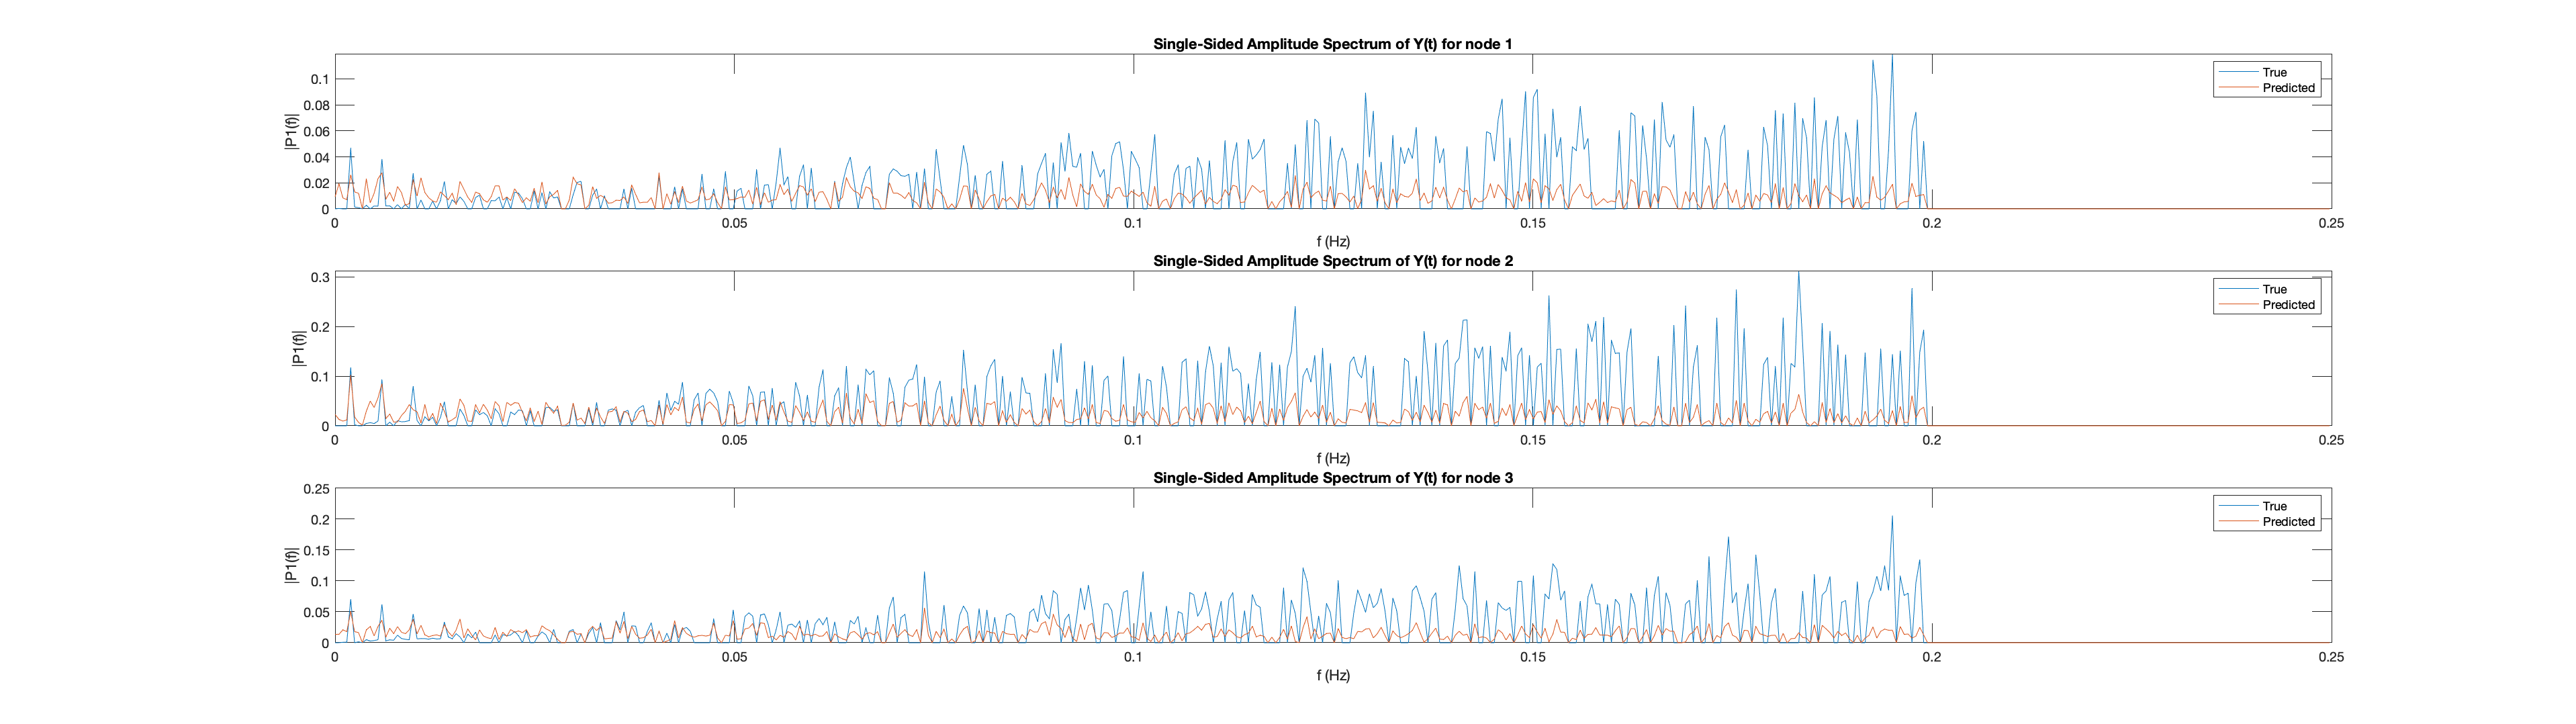

mses = zeros(1, length(output_all));
for i=1:length(output_all)
    mses(i) = cell2mat(cellfun(@(c) {c.statistics.mse}, output_all(i)));
end
[val, ind] = min(mses);
plot_pred_vs_actual(DCM_all{ind}, output_all{ind}, 3, 1)

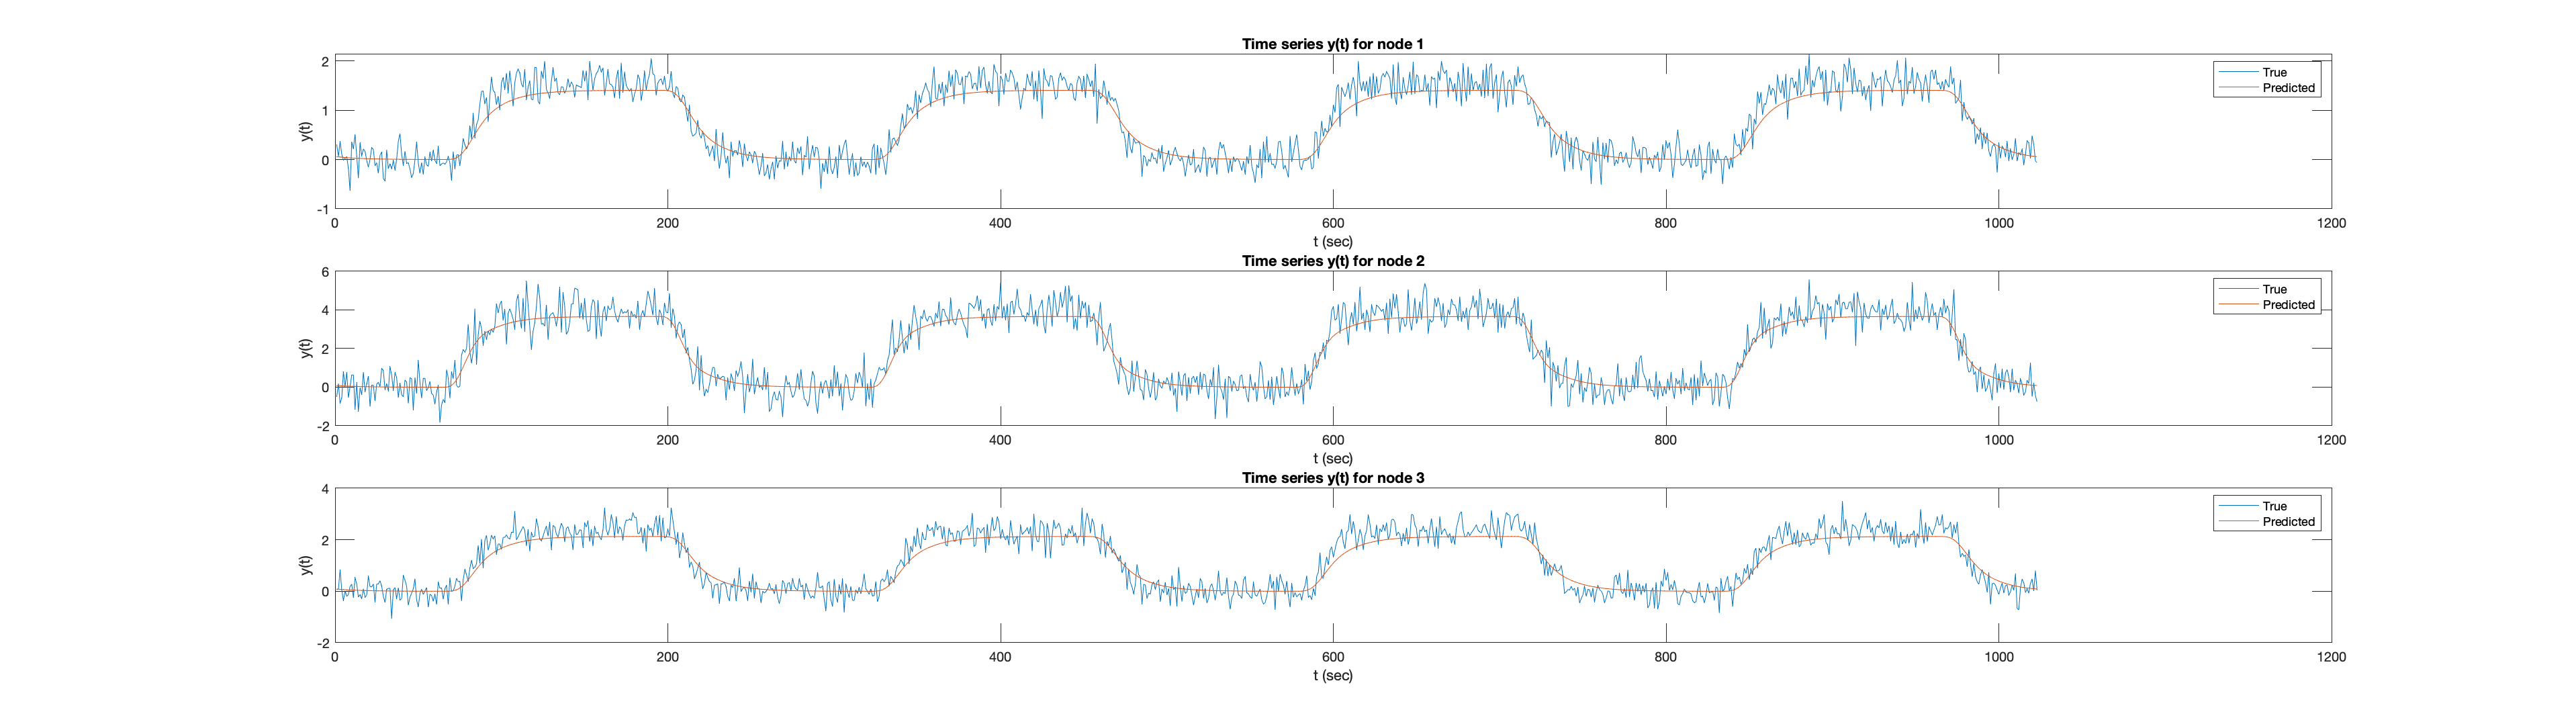

plot_pred_vs_actual(DCM_all{ind}, output_all{ind}, 3, 0)

### Network size effects